% % 0.8 mm for outside radius 
% or = 0.8;
% % 0.4 mm for inside radius 
% ir = 0.4;
% % plot one pearl
% figure
% p = drawPearl(0,0,ir,or);
% plot(p(1,:), p(2,:))
% hold on
% plot(p(3,:), p(4,:))
% % fill outer circle with chosen color
% fill(p(3,:), p(4,:),'b')
% % fill inner circle with white (background color)
% fill(p(1,:), p(2,:),'w')
% axis equal
% grid on
% xlim([-5,5])
% ylim([-5,5])
% hold off

% Testing the pearls with all the colors
drawMultiplePearls(6,36)
xlim([-5, 15])
ylim([0,60])
set(gca, 'YDir','reverse')

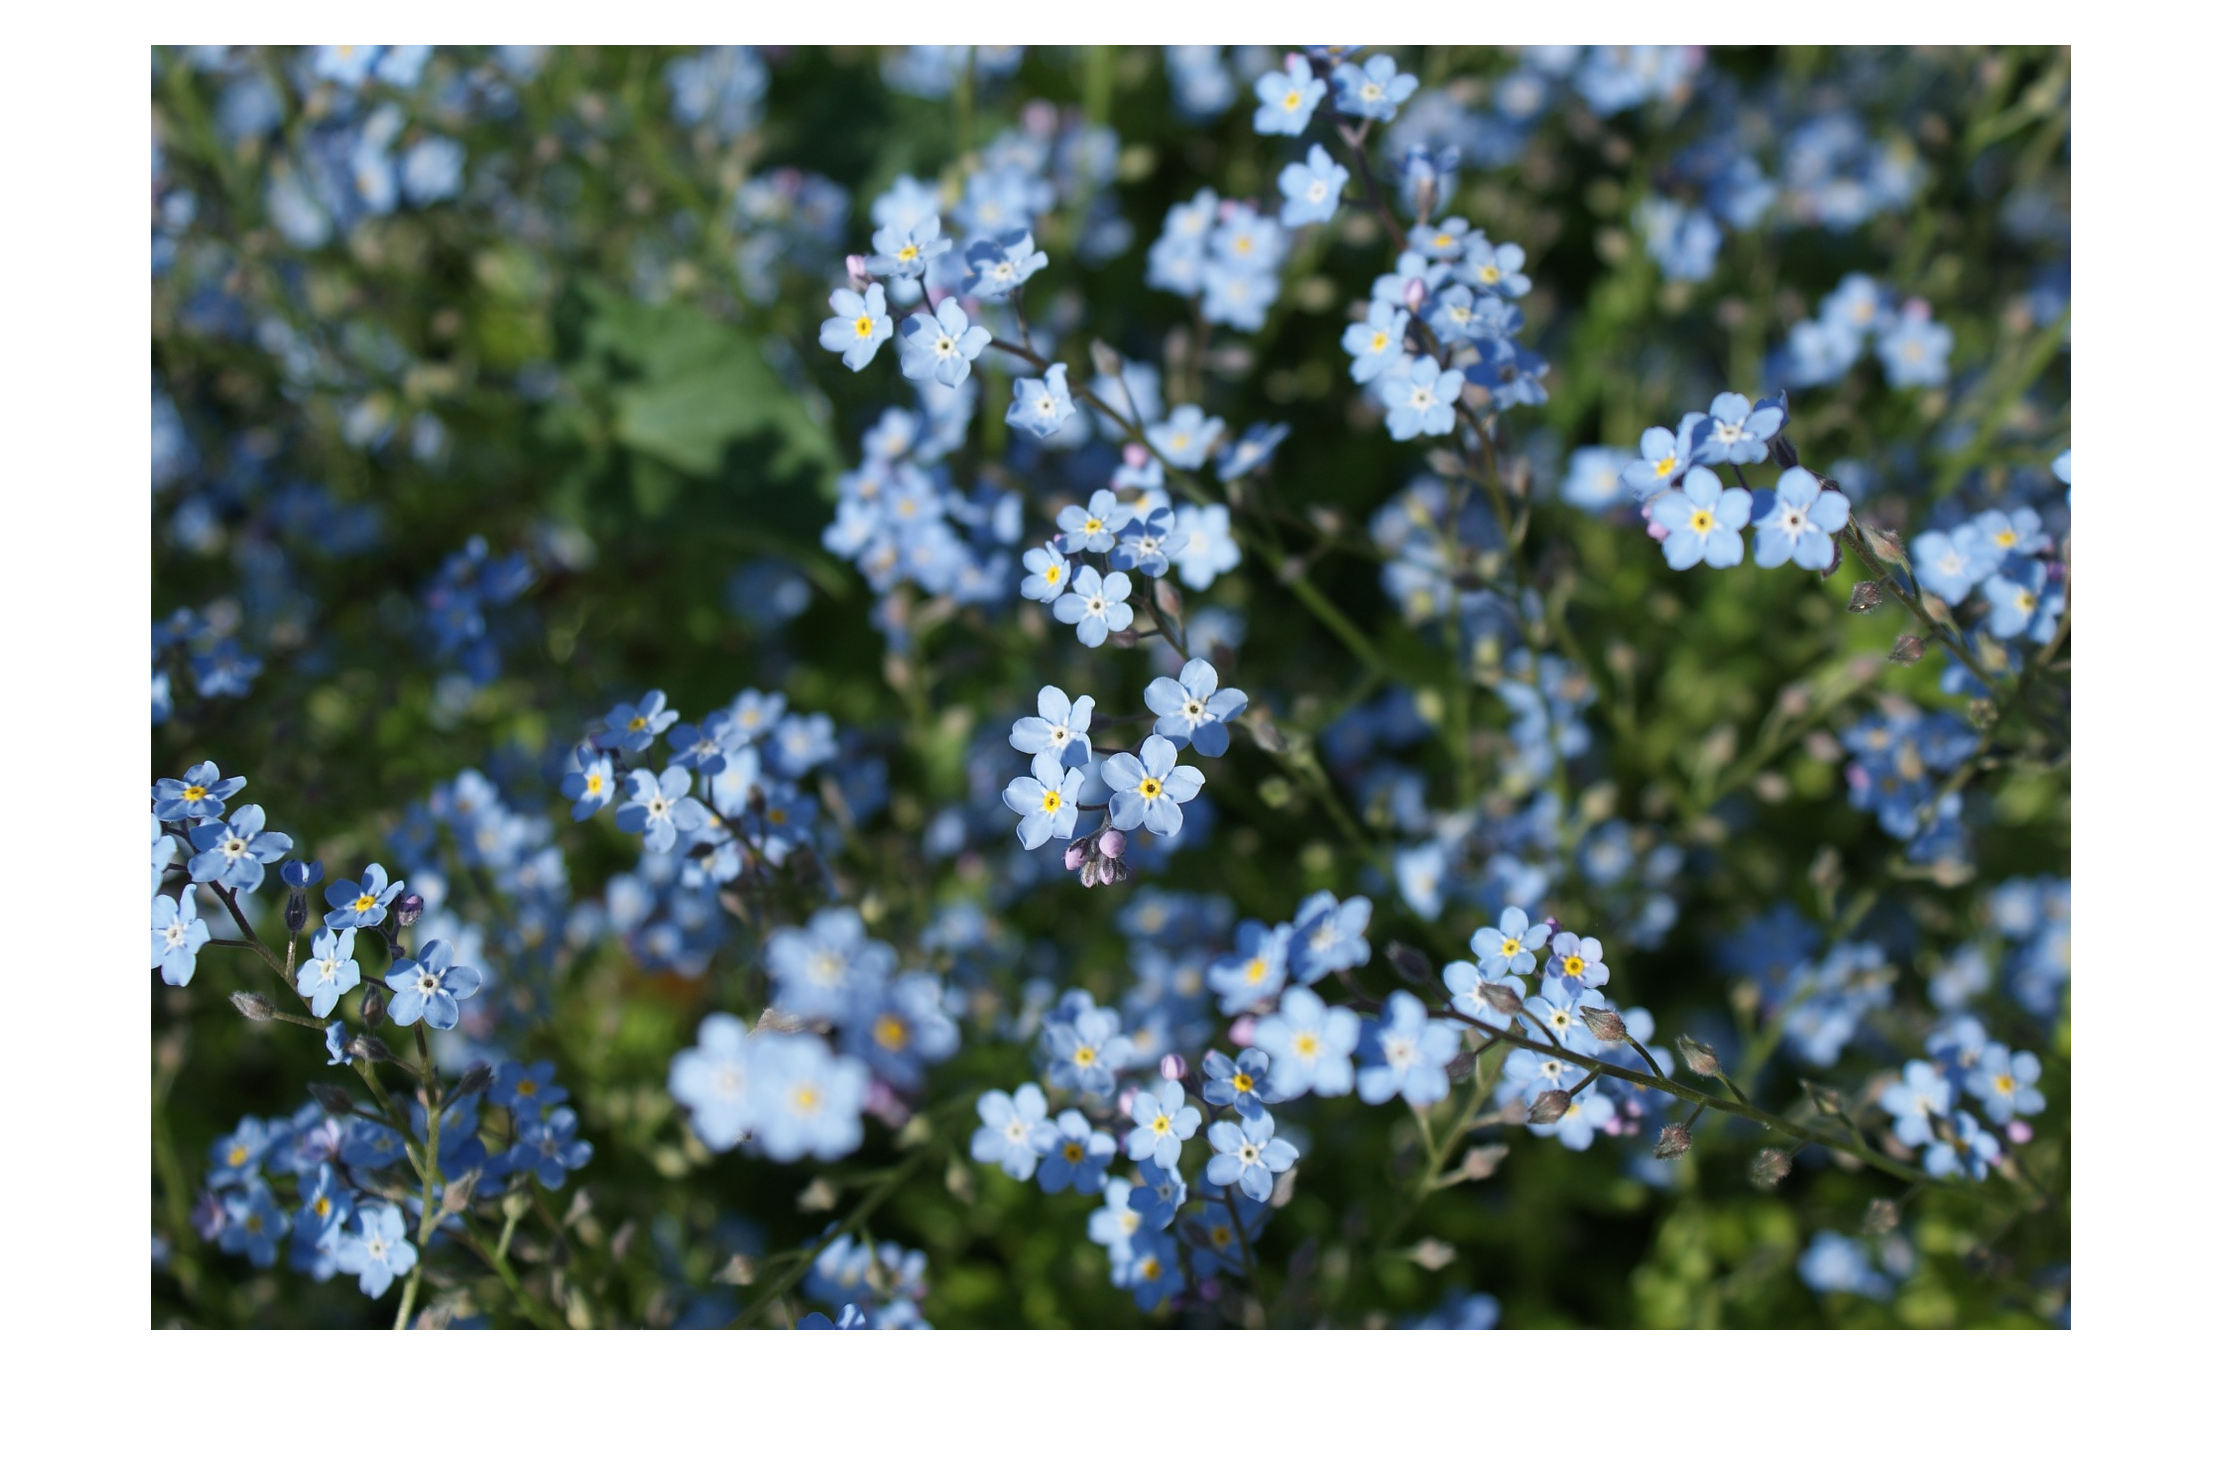

im = im2double(imread('flowers.jpg'));
imshow(im);

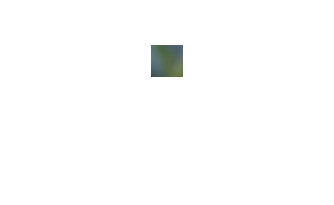

% Test for one pixel
test = 32;
im_test = im(1:test,1:test,:);
imshow(im_test)

im_size = size(im);
% Set the sizes for the reproduced image
im_row = round(im_size(1)/test);
im_col = round(im_size(2)/test);

% Mean value of all the color values
im_average(:,:) = mean(mean(im_test(:,:,:)));
im_average = im_average';
% rgb -> lab
% To be able to compare 
im_average_Lab(:,:) = rgb2lab(im_average); % image 

% all colors in the getColor function color spectrum
all_colours = 1:216;
c_Lab(all_colours,:) = rgb2lab(getColor(all_colours));

% Calculating euclidian distance
E_ab = zeros(1,length(c_Lab));

E_ab(:,all_colours) = sqrt((im_average_Lab(:,1)-c_Lab(all_colours,1)).^2 + (im_average_Lab(:,2)-c_Lab(all_colours,2)).^2 + (im_average_Lab(:,3)-c_Lab(all_colours,3)).^2);


% Find the smallest distance and get its index in the color spectrum 
[min_dis, index] = min(E_ab)

min_dis = 12.5400

index = 87

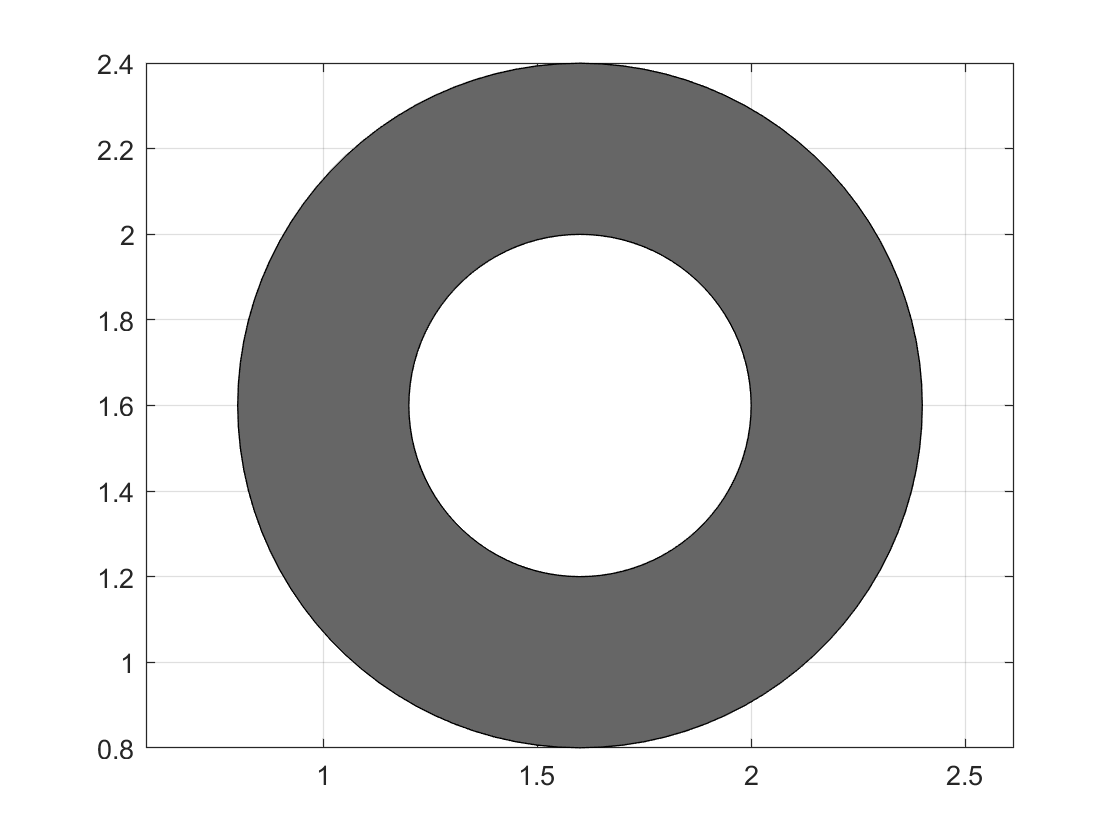

drawMultiplePearls(1,1,index)

% Gör för hela bilden 
im_rep(1:im_row,1:im_col,1) = mean(mean(im(1:test:im_size(1),1:test:im_size(2),1))); 

im(1:test:im_size(1),1:test:im_size(2),1)

ans =     0.3451    0.3451    0.6275    0.3569    0.2235    0.3725    0.8549    0.5216    0.6941    0.2627    0.2941    0.4157    0.5765    0.2784    0.2627    0.2118    0.2549    0.3137    0.4980    0.2902    0.2118    0.1608    0.3137    0.3765    0.5216    0.5765    0.6039    0.4471    0.1922    0.3176    0.3098    0.2549    0.4471    0.6118    0.2471    0.2902    0.2627    0.6039    0.4706    0.3020    0.2275    0.2980    0.3255    0.5294    0.7176    0.2824    0.5725    0.6039    0.5647    0.1529
    0.2353    0.3451    0.2863    0.3412    0.3059    0.4392    0.5608    0.3647    0.6353    0.4471    0.3725    0.3137    0.3216    0.3294    0.2118    0.2824    0.2706    0.5020    0.5020    0.3765    0.0784    0.0784    0.0824    0.3137    0.4510    0.4510    0.2745    0.1373    0.1333    0.2627    0.3294    0.2471    0.2353    0.6078    0.2902    0.6745    0.7294    0.4039    0.5843    0.5843    0.2980    0.2824    0.2745    0.4235    0.2824    0.4627    0.6000    0.6039    0.4353   

im(1*test:test*2, 1*test:test*2, 1)

ans =     0.3725    0.3490    0.3412    0.3294    0.3137    0.3059    0.2863    0.2784    0.2706    0.2431    0.2314    0.2039    0.1804    0.1647    0.1647    0.1608    0.1529    0.1686    0.1647    0.1804    0.1765    0.1804    0.1843    0.1961    0.2039    0.2118    0.2196    0.2314    0.2392    0.2588    0.2706    0.2784    0.2784
    0.3725    0.3451    0.3333    0.3176    0.3137    0.3059    0.2902    0.2706    0.2549    0.2353    0.2157    0.1961    0.1765    0.1608    0.1569    0.1569    0.1647    0.1686    0.1725    0.1804    0.1804    0.1804    0.1765    0.1961    0.2039    0.2078    0.2157    0.2275    0.2353    0.2510    0.2627    0.2706    0.2784
    0.3608    0.3412    0.3333    0.3176    0.3098    0.2980    0.2863    0.2667    0.2510    0.2235    0.2078    0.1882    0.1686    0.1608    0.1529    0.1647    0.1725    0.1686    0.1725    0.1804    0.1804    0.1804    0.1804    0.1922    0.2000    0.2078    0.2118    0.2235    0.2314    0.2471    0.2549    0.2667    0.2745
 


im_rep

im_rep =     0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875
    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875    0.2875

im_average

im_average =     0.3370    0.4173    0.3578



%im_rep = im(1:test:im_size(1),1:test:im_size(2),:)